The next thing I'd be interested in seeing would be the return power (plots from bottomReflectivity.mlx), but now analyzing return times which are well beyond the bedrock echo (say, >35 microseconds) where there should be no reflectors, so we're just seeing instrumental noise), which is another way of checking the amplifier gain.

Looking @ Data_img_02_20231217_01_028.mat

- take data from range bin >2500 (below bedrock) to check for instrumental noise (aka amplifier gain)

clear all
close all
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_02_20231217_01_029.mat
load Data_20231217_01_029.mat

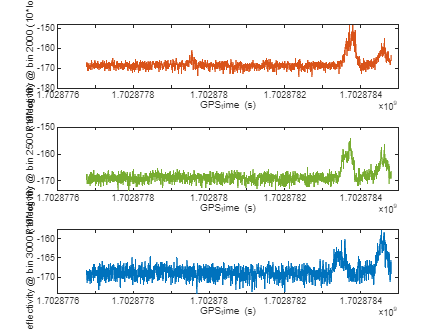

bedRock2250 = Data(2250, :); % data pulled from bin 2250

tiledlayout(3, 1)
nexttile
plot(GPS_time, 10*log10(bedRock2250), 'color', "#D95319")
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 2000 (10*log10)')

nexttile
bedRock2500 = Data(2500, :); % data pulled from bin 2500

plot(GPS_time, 10*log10(bedRock2500), 'color', "#77AC30")
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 2500 (10*log10)')

nexttile
bedRock3000 = Data(3000, :); % data pulled from bin 3000

plot(GPS_time, 10*log10(bedRock3000))
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 3000 (10*log10)')

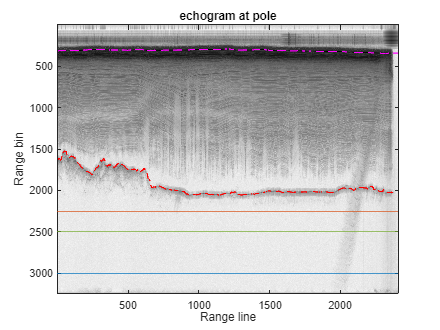

% load echogram!
echo = load('Data_img_02_20231217_01_029.mat','Data','Time','GPS_time');
fig029 = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
title('echogram at pole');
% right side is (0,0)
hold on

layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20231217_01\Data_20231217_01_029.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);

hold on
%reference lines for below bedrock graphs
x = linspace(0, size(Data, 2), size(Data, 2));
yline(2250, 'color', "#D95319")
yline(2500, 'color', "#77AC30")
yline(3000, 'color', "#0072BD")
hold off

ECHOGRAM NEAR POLE:

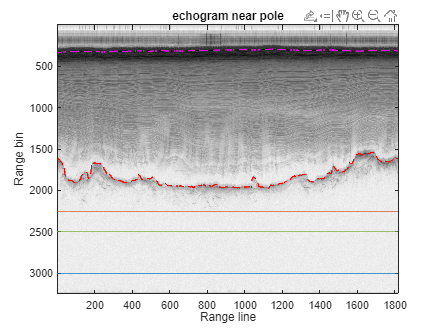

clear all

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20231217_01\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20231217_01\

load Data_img_02_20231217_01_028.mat
load Data_20231217_01_028.mat

% load echogram!
echo = load('Data_img_02_20231217_01_028.mat','Data','Time','GPS_time');
fig028 = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
title('echogram near pole');
hold on

layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20231217_01\Data_20231217_01_028.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);
hold off
hold on
%reference lines for below bedrock graphs
x = linspace(0, size(Data, 2), size(Data, 2));
yline(2250, 'color', "#D95319")
yline(2500, 'color', "#77AC30")
yline(3000, 'color', "#0072BD")
hold off

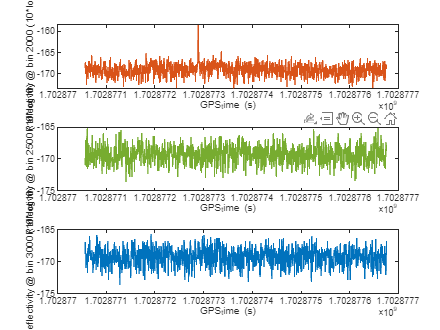

bedRock2250 = Data(2250, :); % data pulled from bin 2250

tiledlayout(3, 1)
nexttile
plot(GPS_time, 10*log10(bedRock2250), 'color', "#D95319")
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 2000 (10*log10)')
%spike on graph is from a dark spot at about ~700 on the range line of the echogram

nexttile
bedRock2500 = Data(2500, :); % data pulled from bin 2500

plot(GPS_time, 10*log10(bedRock2500), 'color', "#77AC30")
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 2500 (10*log10)')

nexttile
bedRock3000 = Data(3000, :); % data pulled from bin 3000

plot(GPS_time, 10*log10(bedRock3000))
xlabel('GPS_time (s)')
ylabel('Reflectivity @ bin 3000 (10*log10)')